**Input**

% Define Cutoff frequency for this EMI Filter
Fcutoff = 5e3

Fcutoff = 5000

% Output impedance of the filter should be much less that input impedance
% of the power supply
% Set input impedance of the power supply:
Zpowerin = 20

Zpowerin = 20

Zfilterout = 1/10*Zpowerin

Zfilterout = 2


%Maximum theoretial Capacitance
Cmax = 100e-6

Cmax = 1.0000e-04


%Calculated Cmin
Cmin = 1/(2*pi*Fcutoff*Zfilterout)

Cmin = 1.5915e-05


%Calcilated Lmin and Lmax
Lmax = 1/(Fcutoff^2*2^2*pi^2*Cmin)

Lmax = 6.3662e-05

Lmin = 1/(Fcutoff^2*2^2*pi^2*Cmax)

Lmin = 1.0132e-05

**Capacitance and Indutance**

L = 10.^(-9:-3) 

L = 1.0e-03 *

    0.0000    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


C = 10.^(-9:-3)

C = 1.0e-03 *

    0.0000    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


f = linspace(1, Fcutoff, 10)

f = 1.0e+03 *

    0.0010    0.5564    1.1119    1.6673    2.2228    2.7782    3.3337    3.8891    4.4446    5.0000


**E24 Row**

% There is a formula to create any of E series of preferred numbers
% We are creating E24
m = 24

m = 24

n = [0:1:m-1]

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


Vn = round(nthroot(10.^n,m), 1)

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.9000    3.2000    3.5000    3.8000    4.2000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000



% But for historical reasons, some of the value in industry are
% substituted, check WIKI
Vn(11) = 2.7

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    2.9000    3.2000    3.5000    3.8000    4.2000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(12) = 3.0

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.2000    3.5000    3.8000    4.2000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(13) = 3.3

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.3000    3.5000    3.8000    4.2000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(14) = 3.6

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.3000    3.6000    3.8000    4.2000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(15) = 3.9

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000    4.2000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(16) = 4.3

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000    4.3000    4.6000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(17) = 4.7

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000    4.3000    4.7000    5.1000    5.6000    6.2000    6.8000    7.5000    8.3000    9.1000


Vn(23) = 8.2

Vn =     1.0000    1.1000    1.2000    1.3000    1.5000    1.6000    1.8000    2.0000    2.2000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000    4.3000    4.7000    5.1000    5.6000    6.2000    6.8000    7.5000    8.2000    9.1000


**Impedances**

Xl = 2*pi.*f'*L

Xl =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0063
    0.0000    0.0000    0.0003    0.0035    0.0350    0.3496    3.4962
    0.0000    0.0001    0.0007    0.0070    0.0699    0.6986    6.9862
    0.0000    0.0001    0.0010    0.0105    0.1048    1.0476   10.4762
    0.0000    0.0001    0.0014    0.0140    0.1397    1.3966   13.9661
    0.0000    0.0002    0.0017    0.0175    0.1746    1.7456   17.4561
    0.0000    0.0002    0.0021    0.0209    0.2095    2.0946   20.9460
    0.0000    0.0002    0.0024    0.0244    0.2444    2.4436   24.4360
    0.0000    0.0003    0.0028    0.0279    0.2793    2.7926   27.9260
    0.0000    0.0003    0.0031    0.0314    0.3142    3.1416   31.4159


Xc = 1./(2*pi.*f'*C)

Xc = 1.0e+08 *

    1.5915    0.1592    0.0159    0.0016    0.0002    0.0000    0.0000
    0.0029    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0007    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Xcmin = 1./(2*pi.*f'*Cmin)

Xcmin = 1.0e+04 *

    1.0000
    0.0018
    0.0009
    0.0006
    0.0004
    0.0004
    0.0003
    0.0003
    0.0002
    0.0002


Xcmax = 1./(2*pi.*f'*Cmax)

Xcmax = 1.0e+03 *

    1.5915
    0.0029
    0.0014
    0.0010
    0.0007
    0.0006
    0.0005
    0.0004
    0.0004
    0.0003


Xlmax = 2*pi.*f'*Lmax

Xlmax =     0.0004
    0.2226
    0.4448
    0.6669
    0.8891
    1.1113
    1.3335
    1.5556
    1.7778
    2.0000


Xlmin = 2*pi.*f'*Lmin

Xlmin =     0.0001
    0.0354
    0.0708
    0.1061
    0.1415
    0.1769
    0.2122
    0.2476
    0.2829
    0.3183


**Calculate our Filter**

% Estimate middle point in our range:
Zmin = sqrt(Lmin/Cmax)

Zmin = 0.3183

Zaverage = (Zfilterout + Zmin)/2

Zaverage = 1.1592

Cfilter = 1/(2*pi*Fcutoff*Zaverage)

Cfilter = 2.7461e-05

Lfilter = 1/(Fcutoff^2*2^2*pi^2*Cfilter)

Lfilter = 3.6897e-05



%extract number to round it to E24
tempCstring = num2str(Cfilter, '%.2e') % Convert number to a scientific notation string with 2 decimal places of precision

tempCstring = '2.75e-05'

tempCstringParts = strsplit(tempCstring,'e') % Split the string where 'e' is

tempCstringParts = 1×2 cell array
    {'2.75'}    {'-05'}


tempCfirstPart = str2double(tempCstringParts(1)) % Get the 1st part of stringParts which is the first part of standard form.

tempCfirstPart = 2.7500


%Finding closest value from E24 row
[j,i] = min(abs(Vn-tempCfirstPart))

j = 0.0500

i = 11


%Return Scientific part:
Cpower = str2double(tempCstringParts(2))

Cpower = -5

Cfilter = Vn(i)*10^Cpower

Cfilter = 2.7000e-05


%extract number to round it to E24
tempLstring = num2str(Lfilter, '%.2e') % Convert number to a scientific notation string with 2 decimal places of precision

tempLstring = '3.69e-05'

tempLstringParts = strsplit(tempLstring,'e') % Split the string where 'e' is

tempLstringParts = 1×2 cell array
    {'3.69'}    {'-05'}


tempLfirstPart = str2double(tempLstringParts(1)) % Get the 1st part of stringParts which is the first part of standard form.

tempLfirstPart = 3.6900


%Finding closest value from E24 row
[j,i] = min(abs(Vn-tempLfirstPart))

j = 0.0900

i = 14


%Return Scientific part:
Lpower = str2double(tempLstringParts(2))

Lpower = -5

Lfilter = Vn(i)*10^Lpower

Lfilter = 3.6000e-05


Fourcutofffilter = 1/(2*pi*sqrt(Cfilter*Lfilter))

Fourcutofffilter = 5.1049e+03

Zourfilter = sqrt(Lfilter/Cfilter)

Zourfilter = 1.1547

**Building a plot**

hold on

%Plotting Filter limits:
HanPlotA(1) = plot(f,Xcmin,'b', 'LineWidth', 2)

HanPlotA =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 556.4444 1.1119e+03 1.6673e+03 2.2228e+03 2.7782e+03 3.3337e+03 3.8891e+03 4.4446e+03 5000]
              YData: [10000 17.9712 8.9937 5.9976 4.4989 3.5994 2.9997 2.5713 2.2499 2]

  Show all properties


HanPlotA(2) = plot(f,Xcmax, 'c', 'LineWidth', 2)

HanPlotA =   1×2 Line array:

    Line    Line


HanPlotB(1) = plot(f,Xlmin, 'y', 'LineWidth', 2)

HanPlotB =   Line with properties:

              Color: [1 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 556.4444 1.1119e+03 1.6673e+03 2.2228e+03 2.7782e+03 3.3337e+03 3.8891e+03 4.4446e+03 5000]
              YData: [6.3662e-05 0.0354 0.0708 0.1061 0.1415 0.1769 0.2122 0.2476 0.2829 0.3183]

  Show all properties


HanPlotB(2) = plot(f,Xlmax, 'm', 'LineWidth', 2)

HanPlotB =   1×2 Line array:

    Line    Line



% Adding target impedane line to the plot
HanPlotC(1) = yline(Zfilterout, 'r--', 'LineWidth', 1)

HanPlotC =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 2
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 1
            Label: ''
      DisplayName: ''

  Show all properties


% Adding Cuttof frequency lineto the plot
HanPlotC(2) = xline(Fcutoff, 'k--', 'LineWidth', 1)

HanPlotC =   1×2 ConstantLine array:

    ConstantLine    ConstantLine



grid on

%Plot cutoff and Impedane of our Filter:
HanPlotD = plot(Fourcutofffilter, Zourfilter,'x', 'MarkerSize', 20, 'LineWidth', 2)

HanPlotD =   Line with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: 'none'
          LineWidth: 2
             Marker: 'x'
         MarkerSize: 20
    MarkerFaceColor: 'none'
              XData: 5.1049e+03
              YData: 1.1547

  Show all properties



yscale log
ylim([1e-3 1e3])
ylabel('Impedance [Ohm]')

xscale log
xlim([1e0 1e6])
title ("Impedance Paper")
xlabel('Frequency [Hz]')
xticklabels({'1Hz','10Hz','100Hz', '1k', '10k', '100k', '1M'})

% Adding legend for every plot
Ax1=axes('Visible','Off')

Ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


legend(Ax1, HanPlotA(:), {['C=' num2str(round(Cmin/1e-6, 1)) 'uF']; ...
    ['C=' num2str(round(Cmax/1e-6, 1)) 'uF']}, "Position", [0.1507 0.6099 0.1899, 0.0783])
Ax2=axes('Visible','Off')

Ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


legend(Ax2, HanPlotB(:), {['L=' num2str(round(Lmin/1e-6, 1)) 'uH']; ...
    ['L=' num2str(round(Lmax/1e-6, 1)) 'uH']}, "Position", [0.1507 0.3087 0.1899, 0.0783])
Ax3=axes('Visible','Off')

Ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


legend(Ax3, HanPlotC(:), {['Filter Output Impedance = ' num2str(Zfilterout) ' Ohm']; ...
    ['Cutoff Frequency = ' num2str(Fcutoff/1e3) ' kHz']}, 'Location', 'southeast')
Ax4=axes('Visible', 'Off')

Ax4 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


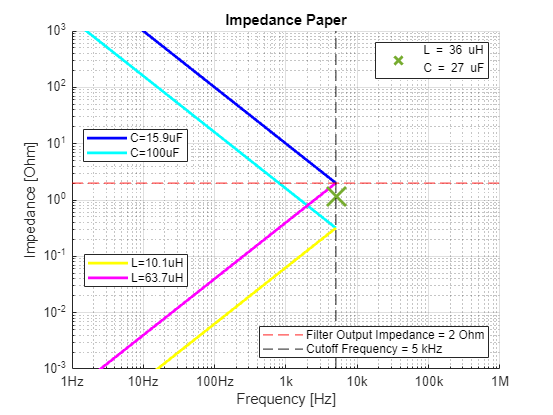

legend(Ax4, HanPlotD, ['L = ' num2str(Lfilter*1e6) ' uH' ...
    '\newline' ...
    'C = ' num2str(Cfilter*1e6) ' uF'])

hold off